f0=60;
T0=1/f0;
time=0:1/(100*f0):T0;
x=f(time);
l=length(x);
g=length(time);
x_1=FourierSeries(x,T0,1);
x_2=FourierSeries(x,T0,2);
x_5=FourierSeries(x,T0,5);
x_15=FourierSeries(x,T0,99);

e_1=sum(abs(x-x_1));
e_2=sum(abs(x-x_2));
e_5=sum(abs(x-x_5));
e_15=sum(abs(x-x_15));

subplot(2,2,1)
plot(time,x,'--')
hold

Current plot held


plot(time,x_1)
title('3 coefficients')
xlabel('time (t)')
ylabel('y')

subplot(2,2,2)
plot(time,x,'--')
hold

Current plot held


plot(time,x_2)

title('5 coefficients')
xlabel('time (t)')
ylabel('y')

subplot(2,2,3)
plot(time,x,'--')
hold

Current plot held


plot(time,x_5)

title('11 coefficients')
xlabel('time (t)')
ylabel('y')

subplot(2,2,4)
plot(time,x,'--')
hold

Current plot held


plot(time,x_15)

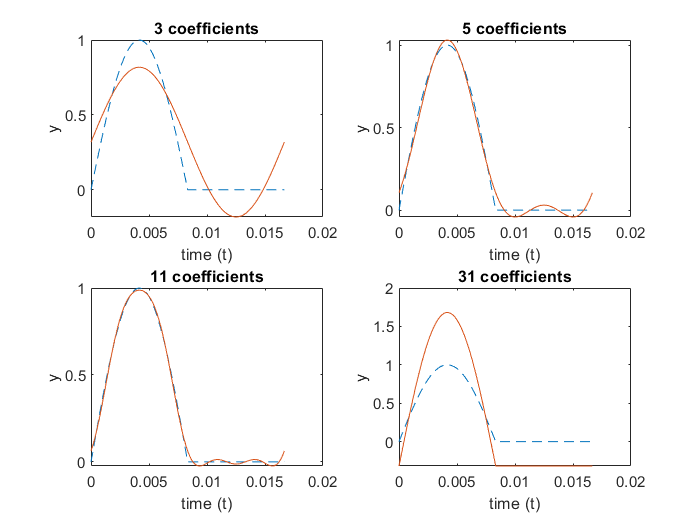

title('31 coefficients')
xlabel('time (t)')
ylabel('y')

function y=f(t)
    f0=60;
    T0=1/f0;
    w0=(2*pi)*f0;
    y=(mod(t,T0)<T0/2).*sin(w0*t);
end   
function [f] =FourierSeries (x,T,n)
    dt=T/100;
    t=0:dt:T;
    omega0=(2*pi)/T;
    index=1;     
    for k=-n:n
        c(index)=dt*sum(x.*exp(-1i*k*2*pi*t/T))/(T);        
        index=index+1;
    end    
    
    index_2=1;  
    ce=zeros(1,length(t));    
    for k=-n:n
        ce=ce+c(index_2)*exp(1i*k*omega0*t);        
        index_2=index_2+1;
    end
    f=(ce);
end